# Matlab Graph Scatter Plot Examples

**back to** [**Fan**](https://fanwangecon.github.io)**'s** [**Reusable Matlab**](https://fanwangecon.github.io/M4Econ/)** Repository or** [**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repository**

Generate k + b = w, color for each w, vectors of k and b such that k + b = w for each w

There are two N by M matrix, A anb B.

Values in Matrix A correspond to the x-axis, values in Matrix B correspond to the y-axis.

The rows and columns in matrix A and B have some other meanings. In this case, we will give color to the columns.

The columns is represented by vector C, which is another variable.

- Each line a different color representing variable 3

- Legend labeling a subset of colors

- X and Y could be asset choices, color could be utility, consumption etc.

## Setting Up Data

close all
clear all

% Bounds
fl_b_bd = -10;
% Max and Mins
fl_w_max = 50;
fl_w_min = fl_b_bd;
fl_kp_max = fl_w_max - fl_b_bd;
fl_kp_min = 0;

% Grid Point Counts
it_w_i = 30;
it_kb_j = 30;

% Grids
ar_w = linspace(fl_w_min, fl_w_max, it_w_i);
ar_kp = linspace(fl_kp_min, fl_kp_max, it_kb_j);
mt_bp = ar_w - ar_kp';
mt_kp = ar_w - mt_bp;
mt_bl_constrained = (mt_bp < fl_b_bd);
mt_bp_wth_na = mt_bp;
mt_kp_wth_na = mt_kp;
mt_bp_wth_na(mt_bl_constrained) = nan;
mt_kp_wth_na(mt_bl_constrained) = nan;

% Flatten
ar_bp_mw_wth_na = mt_bp_wth_na(:);
ar_kp_mw_wth_na = mt_kp_wth_na(:);
ar_bp_mw = ar_bp_mw_wth_na(~isnan(ar_bp_mw_wth_na));
ar_kp_mw = ar_kp_mw_wth_na(~isnan(ar_kp_mw_wth_na));

## Graphing

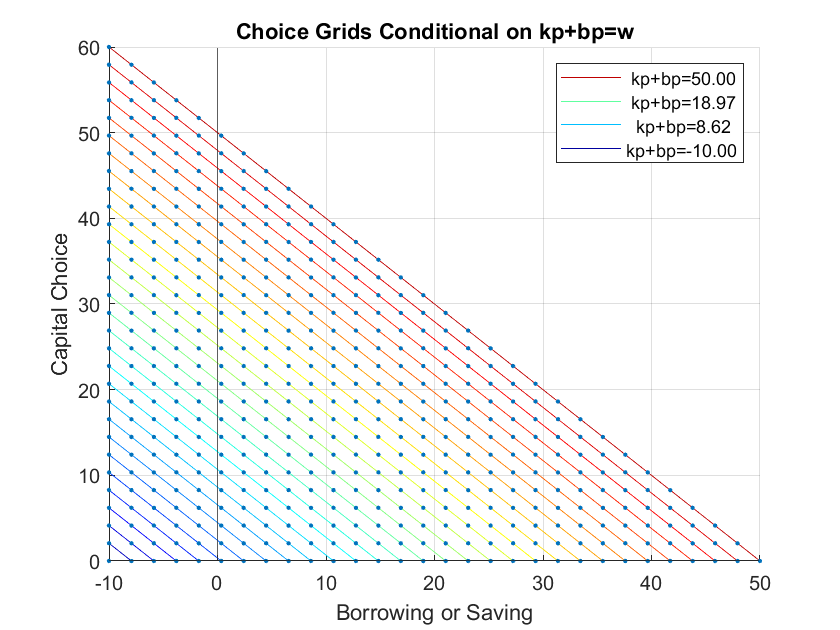

figure('PaperPosition', [0 0 7 4]);
hold on;

chart = plot(mt_bp_wth_na, mt_kp_wth_na, 'blue');

clr = jet(numel(chart));
for m = 1:numel(chart)
   set(chart(m),'Color',clr(m,:))
end
if (length(ar_w) <= 50) 
    scatter(ar_bp_mw, ar_kp_mw, 5, 'filled');
end
xline(0);
yline(0);

title('Choice Grids Conditional on kp+bp=w')
ylabel('Capital Choice')
xlabel({'Borrowing or Saving'})
legend2plot = fliplr([1 round(numel(chart)/3) round((2*numel(chart))/4)  numel(chart)]);
legendCell = cellstr(num2str(ar_w', 'kp+bp=%3.2f'));
legend(chart(legend2plot), legendCell(legend2plot), 'Location','northeast');

grid on;